## NAME:                    MOSUDI ISIAKA

## REG. NUMBER:     PG823362:

## COURSE CODE:    CME710 

## COURSE:               ADVANCED ENGINEERING MATHEMATICS

## DEPT:                     TELECOMMUNICATION ENGINEERING

## **APPLICATION:      MATLAB R2017a(LIVE SCRIPT)**

## **DATE:                    MARCH, 2018**

# **Compare numerical solutions for the differential equation, **

# **    y' = x + y ;  given y(0) = 0, h = 0.1 and h = 0.2**

# **Using Euler, Improved modified Euler and Runge-Kutta methods**

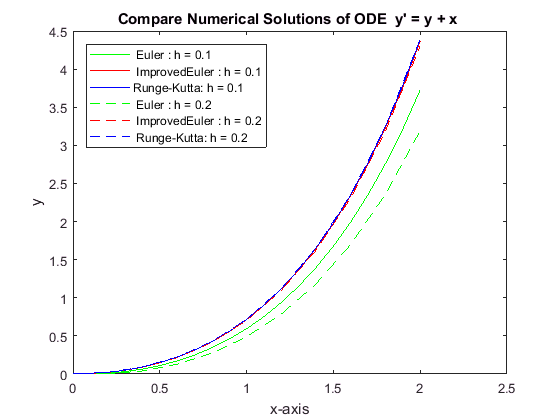

clear

x=0;y=0;        %% Declare Initial Conditions
x_final=2;      %% Assuming I am expected to stop iteration at x=2

h=0.1;                                         %% Plot for step size, h=0.1
[t1,data1] = eulerm(x,y,h,x_final);            %% Euler method
[t2,data2] = eulermimproved(x,y,h,x_final);    %% Improved Euler method
[t3,data3] = rungek(x,y,h,x_final);            %% Runge-Kutta method
plot(t1,data1,'color','g'); hold on;
plot(t2,data2,'color','r')
plot(t3,data3,'color','b')

h=0.2;                                         %% Plot for step size, h=0.2
[t4,data4] = eulerm(x,y,h,x_final);            %% Euler method
[t5,data5] = eulermimproved(x,y,h,x_final);    %% Improved Euler method
[t6,data6] = rungek(x,y,h,x_final);            %% Runge-Kutta method
plot(t4,data4,'g--');
plot(t5,data5,'r--')
plot(t6,data6,'b--')

title("Compare Numerical Solutions of ODE  y' = y + x ");
xlabel('x-axis'); ylabel("y")

legend(' Euler : h = 0.1', ' ImprovedEuler : h = 0.1', ...
    ...
     'Runge-Kutta: h = 0.1 ', ' Euler : h = 0.2', ...
     ...
     ' ImprovedEuler : h = 0.2', ' Runge-Kutta: h = 0.2 ', 'Location','northwest')

## Runge-Kutta 4th Order

function [t, data] = rungek(x,y,h,x_final)
    Nsteps = round(x_final/h);
    t = zeros(Nsteps,1);    data = zeros(Nsteps,1);
    
    t(1) = x; data(1,:) = y; %% store intial condition
    for i =1:Nsteps
        dy = derivs(x,y); k1 = h*dy;
        dy = derivs(x + h/2,y+k1/2); k2 = h*dy;
        dy = derivs(x + h/2,y+k2/2); k3 = h*dy;
        dy = derivs(x + h,y+k3); k4 = h*dy;
        k = (k1 + 2 * k2 + 2 * k3 + k4)/6;
        y = y + k; x = x + h;
        t(i+1) = x; data(i+1,:) = y ; 
    end
end



## Improved Euler Method

function [t, data] = eulermimproved(x,y,h,x_final)
    Nsteps = round(x_final/h);
    t = zeros(Nsteps,1);    data = zeros(Nsteps,1);
    
    t(1) = x; data(1,:) = y; %% store intial condition
    for i =1:Nsteps
        dy = derivs(x,y); k1 = h*dy;
        x = x + h;
        dy = derivs(x, y+k1); k2 = h*dy;
        y = y + (k1 + k2)./2;
        t(i+1) = x; data(i+1,:) = y ; 
   end
end


## Euler Method

function [t, data] = eulerm(x,y,h,x_final)
    Nsteps = round(x_final/h);
    t = zeros(Nsteps,1);    data = zeros(Nsteps,1);
    
    t(1) = x;data(1,:) = y;  %% store intial condition
    for i =1:Nsteps
        dy = derivs(x,y); y = y + h*dy;
        x = x + h;
        t(i+1) = x; data(i+1,:) = y ; 
    end
end

## The differential equation

function dy = derivs(x,y)
    dy = y + x ; 
end
